# Kollmorgen QT-0717 Design Sheet

## Catalog Parameters

T_p = 0.027; %[Nm] - peak torque
w_NL = 1950; %[rad/s] - no load speed
R = 5.7; %[Ohm] - measured terminals resistance
tau_e = 0.12e-3; %[sec] - electrical time constant
J_m = 3.2e-7; %[km m^2] - rotor inertia

### Motor Constants:

### 
$$K_m \equiv \frac{1}\sqrt{\omega_{NL}/T_{peak}} = \frac{K_t}\sqrt{R}  \\
K_t = K_e \\
\tau_E = \frac{L}{R}\\
\tau_M = \frac{R}{K_t^2}\cdot J_{load} = \frac{1}{K_m^2}\cdot J_{load}$$


Km = sqrt(1/(w_NL/T_p));
Kt = Km*sqrt(R); %[Nm/A] - torque constant
Ke = Kt %[V/r/s] - back emf constant

Ke = 0.0089

V_n = Ke*w_NL ; %[V] - nominal voltage
L = tau_e*R;

### Motion Profile

J_ref = 200e-6; %[km*m^2] - reference inertia
theta_ref = deg2rad(10); %[deg] - 
f_ref = 2.0; %[Hz] - expected motion frequency

V_ref = 16.0; %[V] - supply voltage

dtheta_ref = theta_ref*(2*pi*f_ref); %[r/s] - required max speed
ddtheta_ref = theta_ref*(2*pi*f_ref).^2; %[r/s^2] - required max acceleration
T_ref = ddtheta_ref * J_ref; %[Nm] - required max torque

I_ref = T_ref/Kt; %[A] - required max current
tau_m = J_ref/Km^2;

### Motor Chart

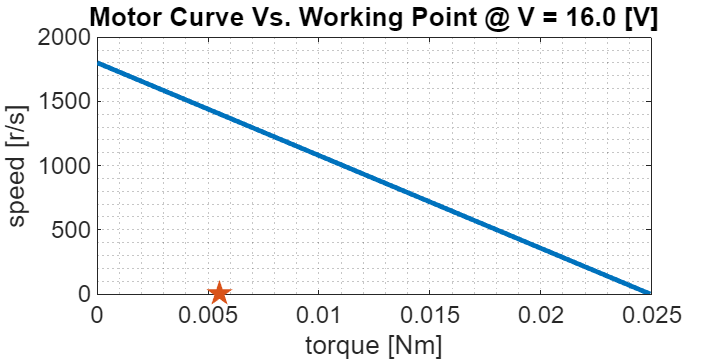

figure('Position',[0 0 600 300])
plot([0;T_p*(V_ref/V_n)], [w_NL*(V_ref/V_n);0], 'LineWidth',3.0,'DisplayName','Motor Curve')
hold on
scatter(T_ref,dtheta_ref, 300, 'filled','Marker','p')
ylabel('speed [r/s]')
xlabel('torque [Nm]')
grid minor
title(sprintf('Motor Curve Vs. Working Point @ V = %.1f [V]', V_ref))
set(gca, 'Fontsize', 15)

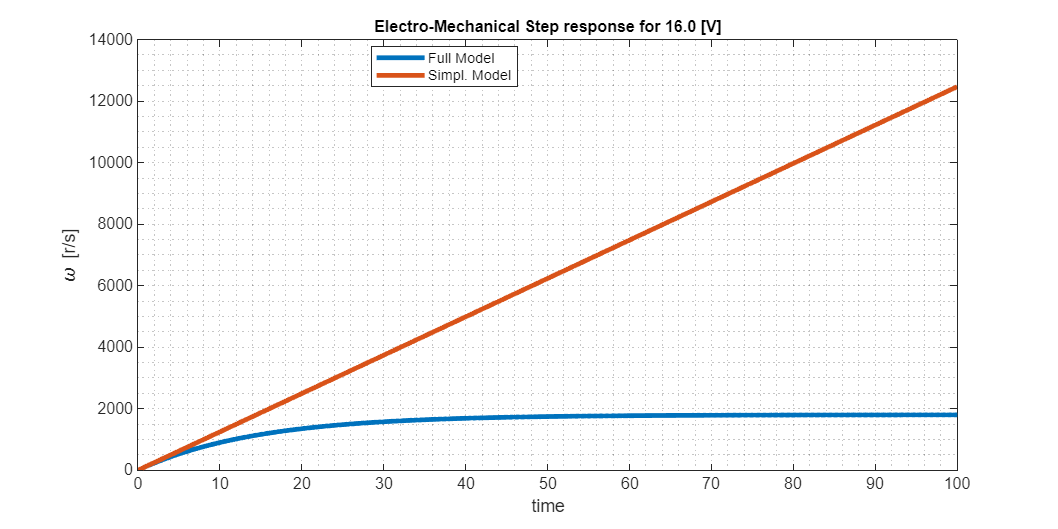

G_m = tf(1/Kt, [tau_e*tau_m tau_e + tau_m 1]);
G_m_simpl = tf(1/Kt, [tau_m 0]);

t_sim = (0:1/10000:100.0)';
u_sim = V_ref*ones(size(t_sim));

y_sim = lsim(G_m, u_sim, t_sim, 0);
y_sim_simpl = lsim(G_m_simpl, u_sim, t_sim, 0);

figure('Position',[0 0 1200 600])
plot(t_sim, y_sim, LineWidth=3.0, DisplayName = 'Full Model');
hold on
plot(t_sim, y_sim_simpl, LineWidth=3.0, DisplayName = 'Simpl. Model');
ylabel('\omega [r/s]')
xlabel('time')
grid minor
set(gca, 'Fontsize', 10.0)
title(sprintf('Electro-Mechanical Step response for %.1f [V]', V_ref), 'FontSize',10)

legend('show', 'Location', 'best', 'ItemHitFcn', @clickLegendToHide)

% ylim([0 5])
stepinfo(y_sim, t_sim)

ans = struct with fields:
         RiseTime: 31.6118
    TransientTime: 55.8264
     SettlingTime: 55.8264
      SettlingMin: 1.6193e+03
      SettlingMax: 1.7992e+03
        Overshoot: 0
       Undershoot: 0
             Peak: 1.7992e+03
         PeakTime: 100
